% This script file creates a plot for the part-03 of the experiment - 01

% Date: August 05, 2019
% Dr. Vibhav Durgesh
% Rev - 0.0
% Rev - 1.0 Modify for FA-2020
%----END-----------------------------
clear all
close all
clc

## Setting up the values of mean and std for normal distribution function

xpri = [0.0 0.0 0.0 3.0]; % Setting the true mean values
sigma = [0.75 1.00 2.0 2.0]; % Setting standard deviation values

## Setting x-value range

x = (-7:0.1:7); % Generating points between -7 and 7 with interval of 0.1

## Generating data for normal distribution function

for i = 1:4
    p(:,:,i) = (1/(sigma(i)*sqrt(2*pi))) .* exp(-0.5*((x-xpri(i))/sigma(i)).^2);
end

## Generating figure with specific size

figure(1)
set(gcf,'unit','inches','position',[0.50 0.50, 6.50 3.50],...
    'defaultaxesfontsize',10,'defaultaxesfontname','times');

## Plotting data with different color lines

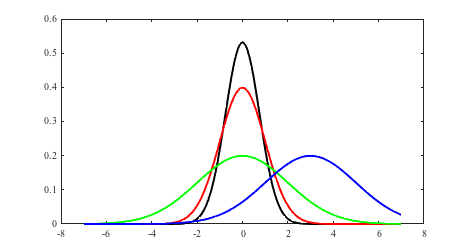

plot(x,p(:,:,1),'k-','linewidth',2);hold on
plot(x,p(:,:,2),'r-','linewidth',2);
plot(x,p(:,:,3),'g-','linewidth',2);
plot(x,p(:,:,4),'b-','linewidth',2);

## Setting xlabel and x-limit and y-limit

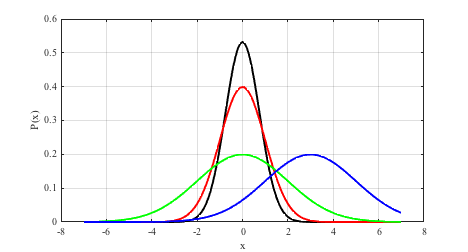

xlabel('x')
ylabel('P(x)')
ylim([0 0.6])
xlim([-8 8])
grid on

## Setting legend and title

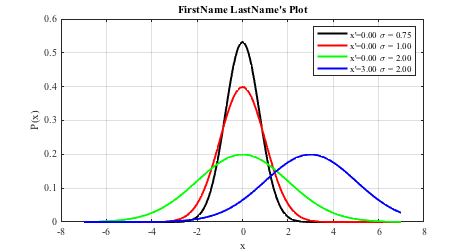

legend('x''=0.00 \sigma = 0.75','x''=0.00 \sigma = 1.00','x''=0.00 \sigma = 2.00','x''=3.00 \sigma = 2.00','location','Northeast')
title('FirstName LastName''s Plot')

## Saving the files in png and pdf format

figName = ('../Figures/FirstName_LastName_ExptNo01_PartC');
set(gcf,'PaperPositionMode','auto')
print(figName,'-dpng','-r600')
set(gcf,'PaperUnits','inches','Units','inches');
figpos = get(gcf, 'Position');
set(gcf, 'PaperSize', figpos(3:4),'Units','inches');
print(figName,'-dpdf','-r600')